%Specify result file route and name
fileNames = ["C:\Users\irene\Desktop\Universidad\Master\KTH\Segundo\Period 1\Research Methodology\Prefetcher-Simulation\results\resnet_no_output.json", "C:\Users\irene\Desktop\Universidad\Master\KTH\Segundo\Period 1\Research Methodology\Prefetcher-Simulation\results\resnet_spghb_output.json", "C:\Users\irene\Desktop\Universidad\Master\KTH\Segundo\Period 1\Research Methodology\Prefetcher-Simulation\results\resnet_spt_output.json"];
names_of_experiments = {'No prefetcher','SPGHB','SPT'};

% Initialize a cell array to store the JSON data
jsonData = cell(numel(fileNames), 1);
% Read the JSON files
for i = 1:numel(fileNames)
    fileName = fileNames{i};
    fileID = fopen(fileName, 'r');
    jsonData{i} = jsondecode(fread(fileID, inf, 'char=>char')');
    fclose(fileID);
end
%%Create directory to store graphs
mkdir('Results_Charts/resnet/');

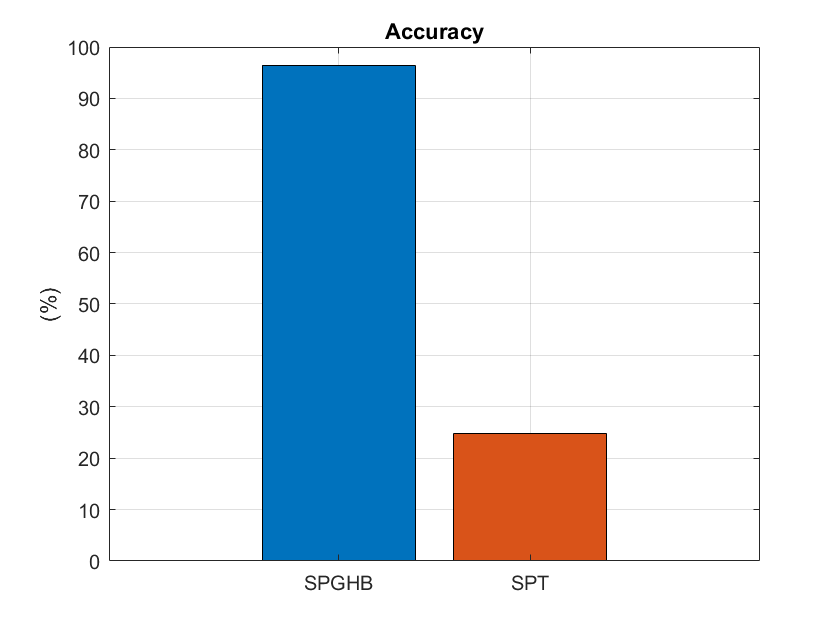

%Plot #1 : Accuracy
prefetched_blocks_read = zeros(numel(fileNames) - 1,1);
total_prefecthed = zeros(numel(fileNames) - 1,1);
accuracy = zeros(numel(fileNames) - 1,1);

for i = 2:numel(fileNames)
    prefetched_blocks_read(i - 1,1)=jsonData{i,1}.roi.cpu0_L1D.usefulPrefetch + jsonData{i,1}.roi.cpu0_L1I.usefulPrefetch;
    total_prefecthed(i - 1,1)=jsonData{i,1}.roi.cpu0_L1D.uselessPrefetch + jsonData{i,1}.roi.cpu0_L1I.uselessPrefetch;
    accuracy(i - 1,1)= 100 * (prefetched_blocks_read(i  - 1,1)/(total_prefecthed(i - 1,1)+prefetched_blocks_read(i - 1,1)));
end

% Create a bar plot with custom colors
barHandle = bar(diag(accuracy), 'stacked');

% Customize the plot (optional)
ylim([0, 100]);
title('Accuracy');
ylabel('(%)');
set(gca, 'XTickLabel', names_of_experiments(2:3)); % Set x-axis labels
grid on;
saveas(gcf, 'Results_Charts/resnet/Accuracy.pdf');

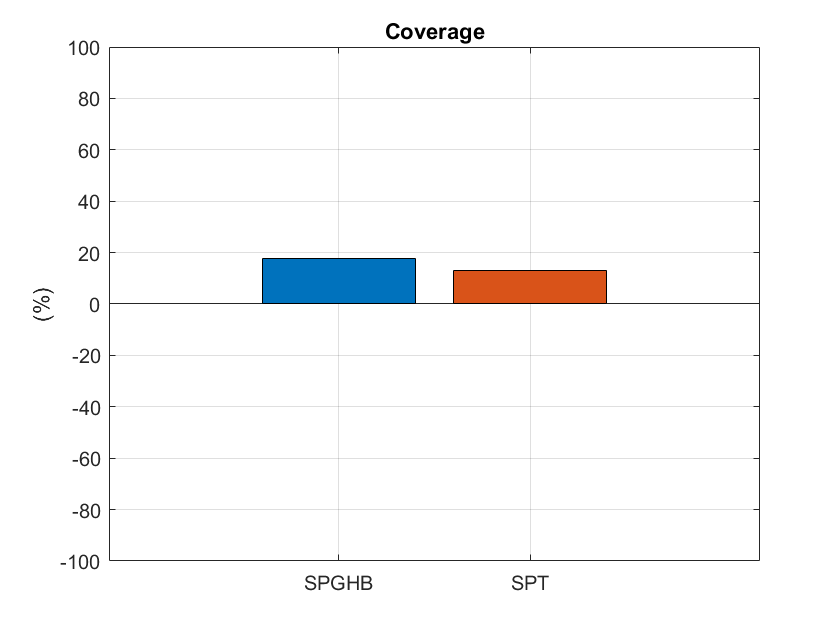

%Plot #2 Coverage 
avoided_misses = zeros(numel(fileNames) - 1,1);
coverage = zeros(numel(fileNames) - 1,1);
for i = 2:(numel(fileNames))
    avoided_misses(i - 1,1)=(jsonData{1,1}.roi.cpu0_L1D.LOAD.miss - jsonData{i,1}.roi.cpu0_L1D.LOAD.miss);
    coverage(i - 1,1)= 100 * (avoided_misses(i - 1,1)/jsonData{1,1}.roi.cpu0_L1D.LOAD.miss );
end

% Create a bar plot with custom colors
barHandle = bar(diag(coverage), 'stacked');

% Customize the plot (optional)
ylim([-100, 100]);
title('Coverage');
ylabel('(%)');
set(gca, 'XTickLabel', names_of_experiments(2:3)); % Set x-axis labels
grid on;
saveas(gcf, 'Results_Charts/resnet/Coverage.pdf');

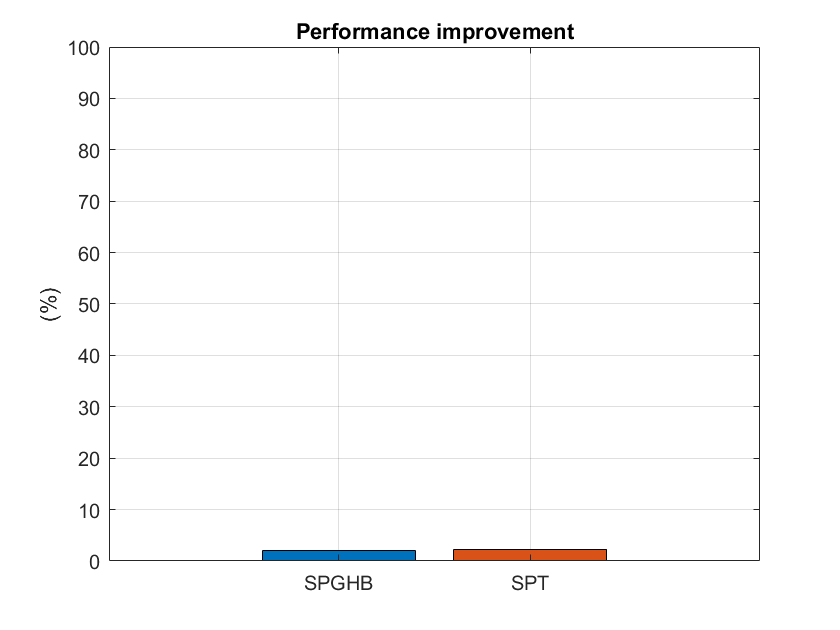

%Plot #3 Performance improvement
IPCprefetchers = zeros(numel(fileNames) - 1,1);
IPCbaseline = (jsonData{1,1}.roi.cores.instructions/jsonData{1,1}.roi.cores.cycles);
perf_improv = zeros(numel(fileNames) - 1,1);
for i = 2:numel(fileNames)
    IPCprefetchers(i-1,1)=(jsonData{i,1}.roi.cores.instructions/jsonData{i,1}.roi.cores.cycles);
    perf_improv(i - 1,1)=100*(IPCprefetchers(i-1,1)/IPCbaseline - 1);
end

% Create a bar plot with custom colors
barHandle = bar(diag(perf_improv), 'stacked');

% Customize the plot (optional)
ylim([0, 100]);
title('Performance improvement');
ylabel('(%)');
set(gca, 'XTickLabel', names_of_experiments(2:3)); % Set x-axis labels
grid on;
saveas(gcf, 'Results_Charts/resnet/Performance improvement.pdf');